# ENERGY CONSUMPTION PREDICTION

Nombre: Jose Rodolfo Valencia Mosquera, Fabio Elias Mera Guadamud[](https://orcid.org/0000-0002-3539-5482)

- Referencia: [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- `SRC: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `DataPort: `

- Sampling Rate=1Hz

- Date = '2021-05-06 00:00:00' AND '2021-11-22 22:04:21'

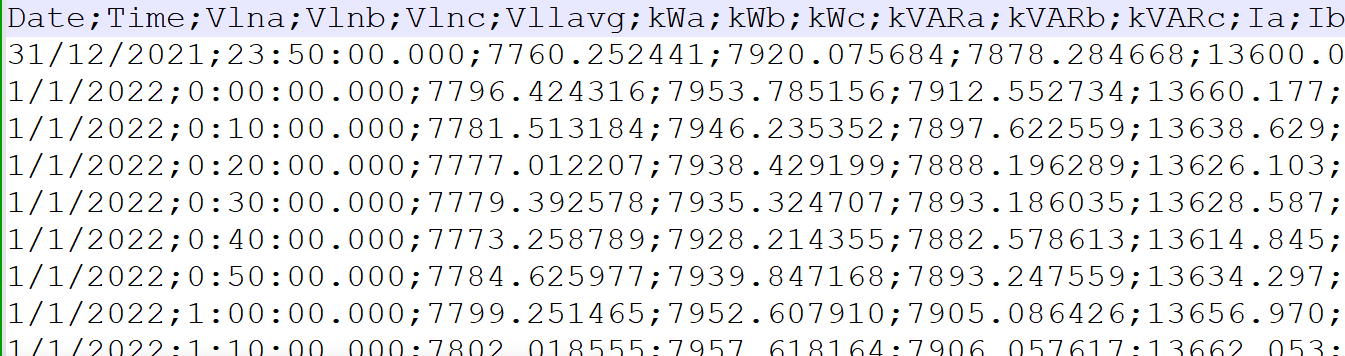

# 1- Load Raw Data

%Antes de ejercutar este codigo, reemplazar los espacios por ";"
clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
filenames = FindTXT(datapath);%List All CSV files
allData=[];
dataNew=[];

for i=1:length(filenames)% Through all files
    data=readtable(fullfile(datapath,filenames(i).name));%Select i CSV file
    %The first 3 columns are deleted: topic, server date, esp32 date, and esp32 date.
    
 dia = [1];
 mes = [2];
 ano = [3];
 Time = [4];
 VLna = [5];
 VLnb = [6];
 VLnc = [7];
 VLLavg = [8];
 kWa = [9];
 kWb = [10];
 kWc = [11];
 kVARa = [12];
 kVARb = [13];
 kVARc = [14];
 Ia = [15];
 Ib = [16];
 Ic = [17];
 kWtotal = [18];
 
  
     data5=[data(:,5)];
     %dataNew=table2cell(data);
     dataNew5=table2array(data5);% Array to Double
     dataNew5(isnan(dataNew5)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew5];
 
     data6=[data(:,6)];
     %dataNew=table2cell(data);
     dataNew6=table2array(data6);% Array to Double
     dataNew6(isnan(dataNew6)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew6];
     
     data7=[data(:,7)];
     %dataNew=table2cell(data);
     dataNew7=table2array(data7);% Array to Double
     dataNew7(isnan(dataNew7)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew7]; 
     
     data9=[data(:,9)];
     %dataNew=table2cell(data);
     dataNew9=table2array(data9);% Array to Double
     dataNew9(isnan(dataNew9)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew9];
     
     data10=[data(:,10)];
     %dataNew=table2cell(data);
     dataNew10=table2array(data10);% Array to Double
     dataNew10(isnan(dataNew10)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew10];
     
     data11=[data(:,11)];
     %dataNew=table2cell(data);
     dataNew11=table2array(data11);% Array to Double
     dataNew11(isnan(dataNew11)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew11];
     
     data12=[data(:,12)];
     %dataNew=table2cell(data);
     dataNew12=table2array(data12);% Array to Double
     dataNew12(isnan(dataNew12)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew12];
     
     data13=[data(:,13)];
     %dataNew=table2cell(data);
     dataNew13=table2array(data13);% Array to Double
     dataNew13(isnan(dataNew13)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew13];
     
     data14=[data(:,14)];
     %dataNew=table2cell(data);
     dataNew14=table2array(data14);% Array to Double
     dataNew14(isnan(dataNew14)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew14];
     
     data18=[data(:,18)];
     %dataNew=table2cell(data);
     dataNew18=table2array(data18);% Array to Double
     dataNew18(isnan(dataNew18)) = 0;%Remove NAN numbers
     dataNew=[dataNew,dataNew18];
     
       
     allData=[allData;dataNew];
     dataNew=[];
  
    
end
%  creando la columna de energia
Energia = allData(:,10)./6;
allData = [allData Energia]

allData = 	1.0e+04 *

    0.7954    0.8007    0.8053    0.2932    0.3120    0.3090    0.0939    0.1008    0.1128    0.9143    0.1524
    0.7959    0.8008    0.8057    0.2910    0.3118    0.3083    0.0922    0.1023    0.1118    0.9111    0.1519
    0.7962    0.8018    0.8064    0.2896    0.3098    0.3060    0.0920    0.1008    0.1120    0.9053    0.1509
    0.7968    0.8021    0.8071    0.2885    0.3092    0.3006    0.0905    0.1018    0.1101    0.8982    0.1497
    0.7975    0.8030    0.8080    0.2866    0.3092    0.3002    0.0918    0.1026    0.1100    0.8959    0.1493
    0.7978    0.8036    0.8082    0.2880    0.3016    0.2965    0.0911    0.1018    0.1109    0.8860    0.1477
    0.7980    0.8040    0.8086    0.2837    0.2993    0.2965    0.0918    0.1003    0.1095    0.8795    0.1466
    0.7844    0.7899    0.7944    0.2746    0.2913    0.2873    0.0828    0.0935    0.1008    0.8532    0.1422
    0.7884    0.7937    0.7978    0.2672    0.2841    0.2782    0.0820    0.0925    0.0999


clear data dataNew;


# 2- Plot Raw Data

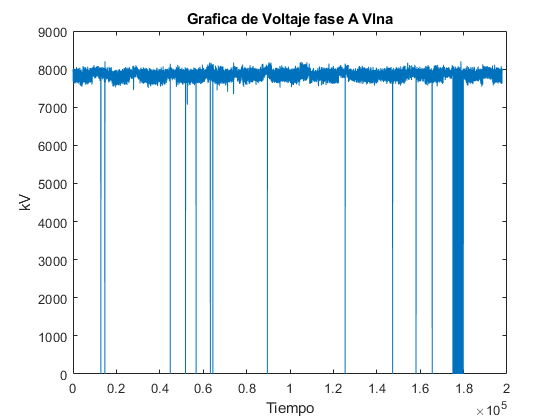

plot(allData(:,1));
title('Grafica de Voltaje fase A Vlna');
xlabel('Tiempo');
ylabel('kV');


% se resumen la tabla, la columna 16 se convierte en la 5


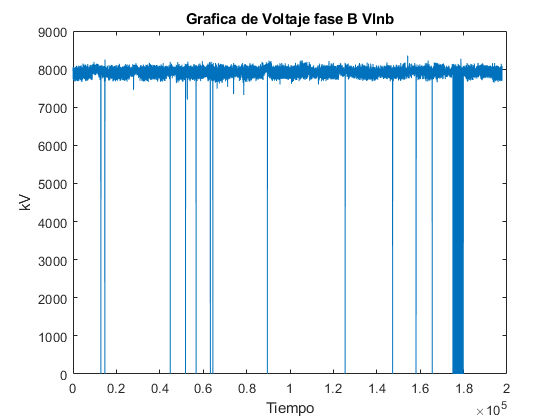

plot(allData(:,2));
title('Grafica de Voltaje fase B Vlnb');
xlabel('Tiempo');
ylabel('kV');

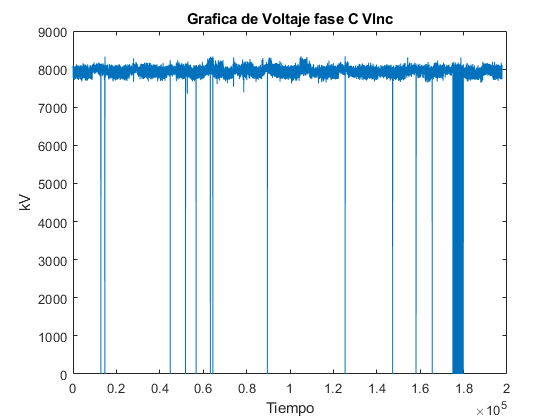

plot(allData(:,3));
title('Grafica de Voltaje fase C Vlnc');
xlabel('Tiempo');
ylabel('kV');

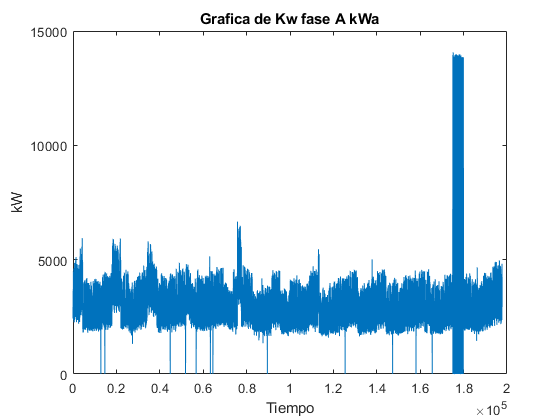

plot(allData(:,4));
title('Grafica de Kw fase A kWa');
xlabel('Tiempo');
ylabel('kW');

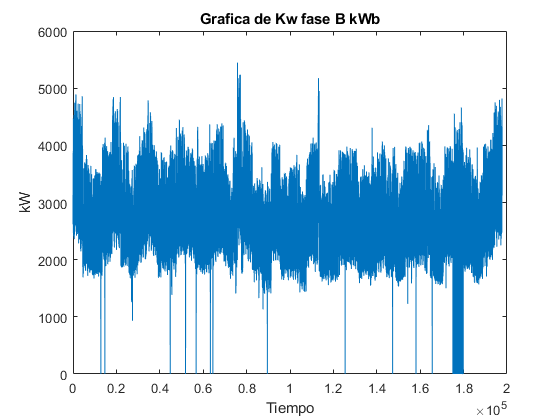

plot(allData(:,5));
title('Grafica de Kw fase B kWb');
xlabel('Tiempo');
ylabel('kW');

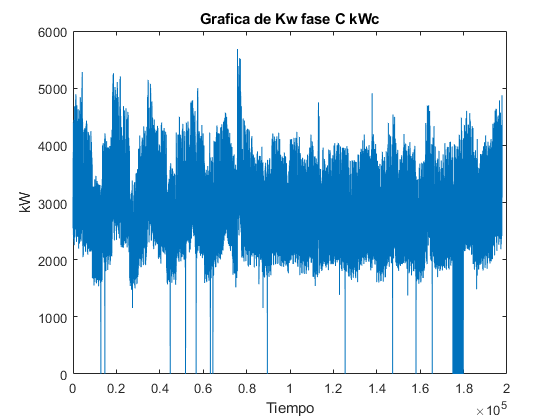

plot(allData(:,6));
title('Grafica de Kw fase C kWc');
xlabel('Tiempo');
ylabel('kW');

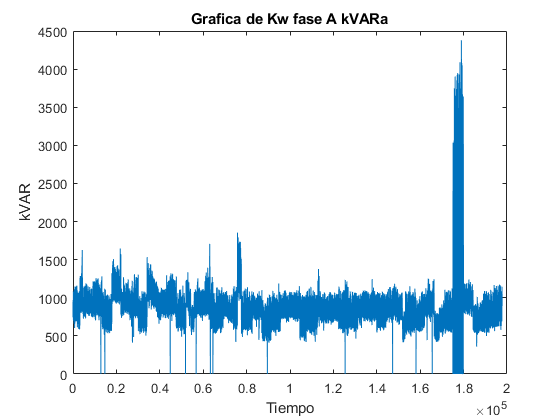


plot(allData(:,7));
title('Grafica de Kw fase A kVARa');
xlabel('Tiempo');
ylabel('kVAR');

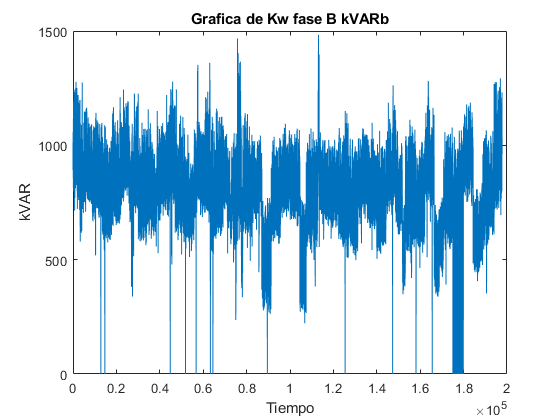

plot(allData(:,8));
title('Grafica de Kw fase B kVARb');
xlabel('Tiempo');
ylabel('kVAR');

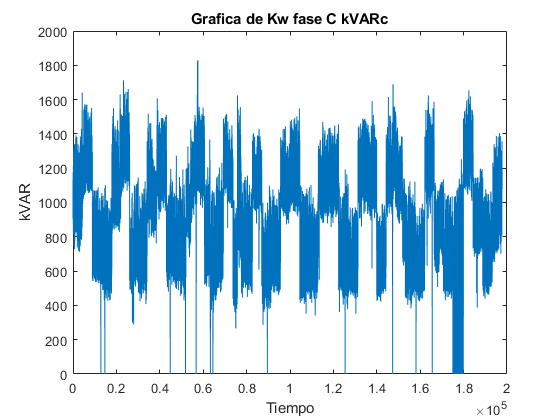


plot(allData(:,9));
title('Grafica de Kw fase C kVARc');
xlabel('Tiempo');
ylabel('kVAR');

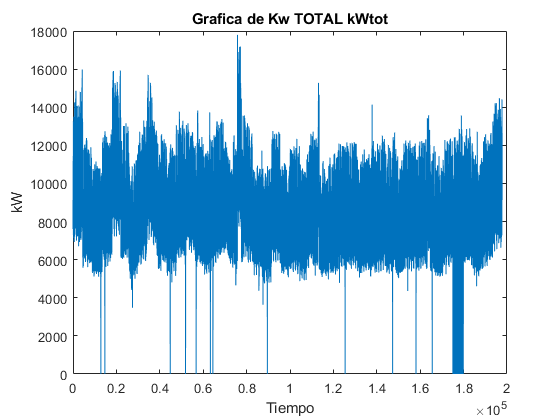

plot(allData(:,10));
title('Grafica de Kw TOTAL kWtot');
xlabel('Tiempo');
ylabel('kW');

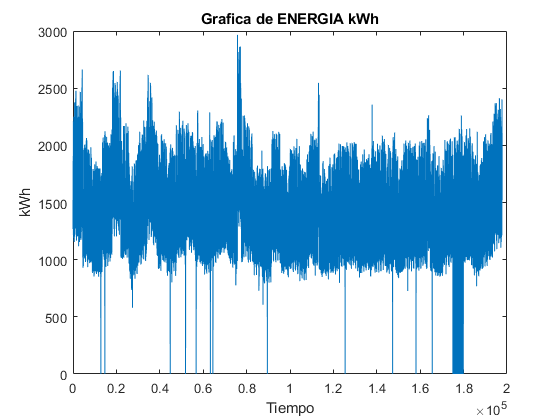

plot(allData(:,11));
title('Grafica de ENERGIA kWh');
xlabel('Tiempo');
ylabel('kWh');

# 3. Preprocesamiento de datos 

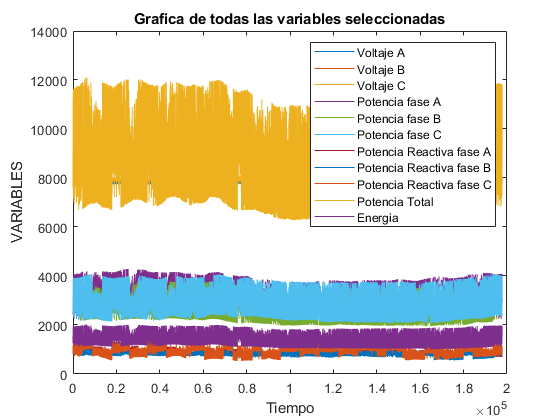

y = hampel(allData,15000,1);
plot (y)
%plot(allData1);
title('Grafica de todas las variables seleccionadas');
xlabel('Tiempo');
ylabel('VARIABLES');
legend('Voltaje A','Voltaje B','Voltaje C','Potencia fase A','Potencia fase B','Potencia fase C','Potencia Reactiva fase A','Potencia Reactiva fase B','Potencia Reactiva fase C','Potencia Total','Energia')

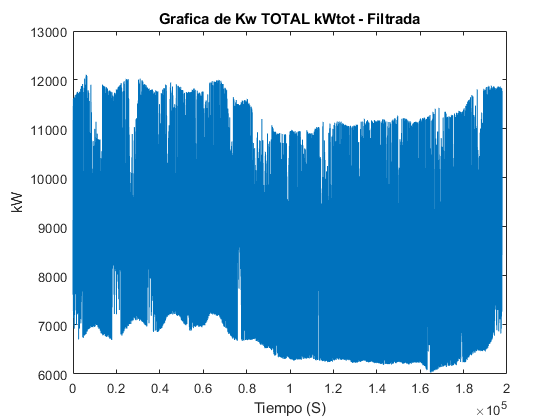

plot (y(:,10))
title('Grafica de Kw TOTAL kWtot - Filtrada');
xlabel('Tiempo (S)');
ylabel('kW');

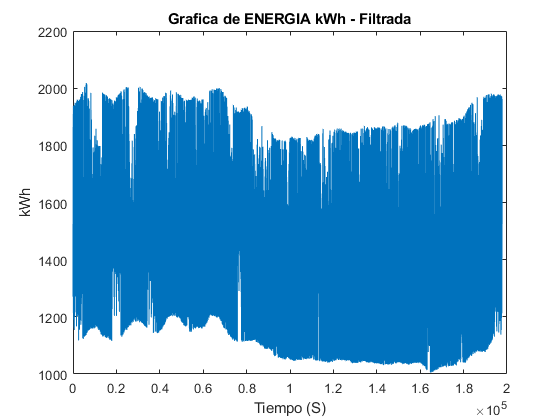


plot (y(:,11))
title('Grafica de ENERGIA kWh - Filtrada');
xlabel('Tiempo (S)');
ylabel('kWh');

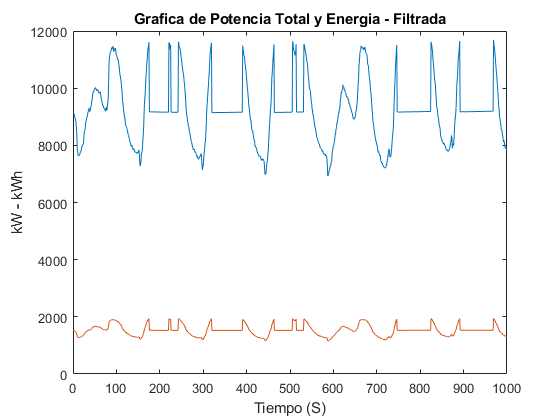


plot (y(1:1000,10))
hold on
plot (y(1:1000,11))
hold off
title('Grafica de Potencia Total y Energia - Filtrada');
xlabel('Tiempo (S)');
ylabel('kW - kWh');

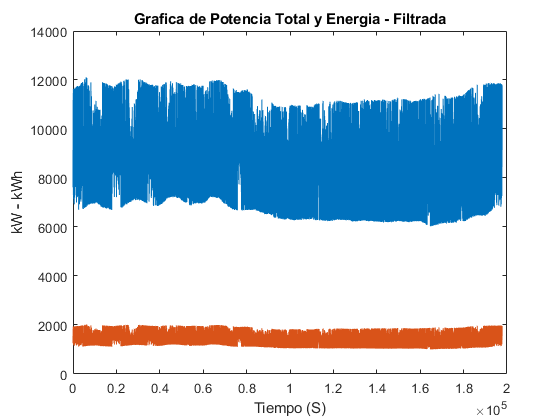

plot (y(:,10))
hold on
plot (y(:,11))
hold off
title('Grafica de Potencia Total y Energia - Filtrada');
xlabel('Tiempo (S)');
ylabel('kW - kWh');

# 4 SELECCION DE CARACTERISTICAS


%corrplot(DataNorm)
%R = corrcoef(y)
threshold = 0.85;%75<-------Maximum correlation value allowed
% Labels:
FeaturesLabels = {'VOLTAJE A','VOLTAJE B','VOLTAJE C','KW A','KW B','KW C','KVAR A','KVAR B','KVAR C','KW TOTAL','ENERGIA kWh'};
    [NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(y,FeaturesLabels,threshold);
LabelsRemove(:)

ans = 2×1 cell array
    {'KW TOTAL'   }
    {'ENERGIA kWh'}


# Cambio de ventana temporal de tiempo a mes

win=6*24*31;% 1 mes
%It takes time to iterate the number of samples / time window.
allDataMean_mes = fData_MeanWin(y(:,10),win);

%Dataset de entrenamiento
input_train_4=[];output_train_4=[];
% inputs: 'Potencia Total (kW)'
input_train_4=allDataMean_mes(1:round(length(allDataMean_mes)*0.70)-1,1);
% output: Energía in the following time step
output_train_4=allDataMean_mes(1+1:round(length(allDataMean_mes)*0.70),1);
% RegressionLinear
Data_train_4=[input_train_4 output_train_4];
%%

%Dataset de validacion
input_val_4=[];output_val_4=[];
% inputs: 'Potencia Total (kW)'
input_val_4=allDataMean_mes(round(length(allDataMean_mes)*0.70):length(allDataMean_mes)-1,1);
% output: Energía in the following time step
output_val_4=allDataMean_mes(round(length(allDataMean_mes)*0.70)+1:length(allDataMean_mes),1);
% Regression Learner
Data_val_4=[input_val_4 output_val_4];

# Validacion de modelo de mes

[trainedModel_POTENCIA_MES_70_F, validationRMSE_POTENCIA_MES_70_F] = trainRegressionModel_POTENCIA_MES_70_F(Data_train_4)

trainedModel_POTENCIA_MES_70_F = struct with fields:
       predictFcn: @(x)svmPredictFcn(predictorExtractionFcn(x))
    RegressionSVM: [1×1 RegressionSVM]
            About: 'This struct is a trained model exported from Regression Learner R2018a.'
     HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 1 columns because this model was trained using 1 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE_POTENCIA_MES_70_F = 143.3667

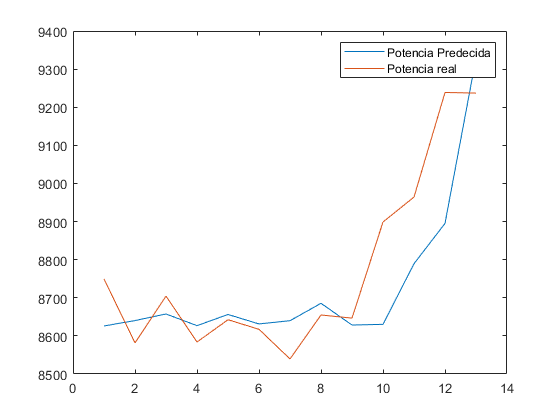

Prediction_MES=trainedModel_POTENCIA_MES_70_F.predictFcn(Data_val_4(:,1));
figure
plot(Prediction_MES);
hold on
plot(Data_val_4(:,2));
legend('Potencia Predecida','Potencia real');

% E = fBar_RmseMseMae(Prediction_hora,Data_val_3(:,2));
rmse = sqrt(immse(Prediction_MES,Data_val_4(:,2)))

rmse = 142.4071

% porcentaje = valor rmse *100 / valor promedio de consumo
porcentaje_error_1_MES = (rmse * 100)/max(Data_val_4(:,2))

porcentaje_error_1_MES = 1.5414

porcentaje_exactitud=100-porcentaje_error_1_MES

porcentaje_exactitud = 98.4586

porcentaje_error_1_MES = (rmse * 100)/mean(Data_val_4(:,2))

porcentaje_error_1_MES = 1.6231

% [rmse,mse,r2] = fBar_RmseMseR2(Prediction_dia,Data_val_3(:,2))
% coeficiente de determinacion
r2=fR2(Prediction_MES,Data_val_4(:,2))

r2 = 0.6169

porcentaje_similitud=1-r2

porcentaje_similitud = 0.3831

% Suma de los cuadrados de la regresión
SSR = sum((Prediction_MES - mean(Data_val_4(:,2))).^2);  
% Suma total de los cuadrados
SST = sum((Data_val_4(:,2) - mean(Data_val_4(:,2))).^2);  
R2=1-SSR/SST

R2 = 0.2741

ex=1-R2

ex = 0.7259

# Calculo de MAPE en 1 mes

% Predicciones del modelo (reemplaza estos valores con las predicciones de tu modelo)
predicciones = [Prediction_MES];

% Valores reales (reemplaza estos valores con los valores reales correspondientes)
valores_reales = [Data_val_4(:,2)];

% Cálculo del error absoluto
error_absoluto = abs(valores_reales - predicciones);

% Cálculo del porcentaje de error absoluto
porcentaje_error_absoluto = (error_absoluto ./ abs(valores_reales)) * 100;

% Cálculo del MAPE (promedio de los porcentajes de error absoluto)
mape = mean(porcentaje_error_absoluto);

% Imprimir el resultado del MAPE
fprintf('El Error de Predicción MAPE es: %.2f%%\n',mape);

El Error de Predicción MAPE es: 1.14%


# Calculo de MAE en 1 mes

% Predicciones del modelo (reemplaza estos valores con las predicciones de tu modelo)
predicciones = [Prediction_MES];

% Valores reales (reemplaza estos valores con los valores reales correspondientes)
valores_reales = [Data_val_4(:,2)];

% Cálculo del error absoluto
error_absoluto = abs(valores_reales - predicciones);

% Cálculo del MAE (promedio de los errores absolutos)
mae = mean(error_absoluto);

% Imprimir el resultado del MAE
fprintf('El MAE (Error Absoluto Medio) es: %.2f\n',mae);

El MAE (Error Absoluto Medio) es: 102.12


# Calculo de MSE en 1 mes

% Predicciones del modelo (reemplaza estos valores con las predicciones de tu modelo)
predicciones = [Prediction_MES];

% Valores reales (reemplaza estos valores con los valores reales correspondientes)
valores_reales = [Data_val_4(:,2)];

% Cálculo del error cuadrático
error_cuadratico = (valores_reales - predicciones).^2;

% Cálculo del MSE (promedio de los errores cuadráticos)
mse = mean(error_cuadratico);

% Imprimir el resultado del MSE
fprintf('El MSE (Mean Squared Error) es: %.2f\n',mse);

El MSE (Mean Squared Error) es: 20279.78
